clc, clf, clear all
%define constants

k_wall = .04; %W/m-K
%sa_wall = total surface area of wall in contact with internal air
sa_wall = (.2*5) + (5.1*5) + (3*5) + (5.1*5) + (.4*5); %m^2
L_wall_vals = .025:.025:0.125; %m

d_floor = 3000; %kg/m^3, based on d for recycled ceramic tile
c_floor = 800; %J/kg-K, based on c for recycled ceramic tile
L_floor = .3:.05:.5; %m %.05:.01:.1;
v_floor = 5.1 * L_floor * 5; %m^3
C_floor = d_floor * v_floor * c_floor; %J/K
sa_floor = 5.1*5; %m^2

sa_window = 2.6*5; %m^2
h_eq_window = .7; %W/m^2-K 

h_in = 15; %W/m^2-K
h_out = 30; %W/m^2-K

%Calculate Resistances, these Rs are defined in doc named
%updatedSimpleModel
R0 = 1/(h_in * sa_floor);

R1 = 1/(h_in * sa_wall);
R2 = L_wall_vals/(k_wall * sa_wall);
R3 = 1/(h_out * sa_wall);

R4 = 1/(h_in * sa_window);
R5 = 1/(h_eq_window * sa_window);
R6 = 1/(h_out * sa_window);

RA = R1 + R2 + R3;
RB = R4 + R5 + R6;

%Looping through possible combinations of L_wall and L_floor and storing
%resulting temperature values for floor and inside air

t_span = linspace(0, 60*60*24*30, 325);

Q_in = @(t) ((-361*cos(pi *t/(12*3600)) + 224*cos(pi * t/(6*3600)) + 210)*sa_window);
T_out_sin = @(t) (-3 + 6*sin((2*pi*t)/(24*60*60)) + (3*pi)/4);

count = 1;
Tfloor_total = []; %zeros(325,5);
Tair_total = []; %zeros(325,5);

while count < 6  %while loop to iterate through array of Lwall values
    L_wall = L_wall_vals(count);
%Resetting resistors for each new L_wall value
    R2 = L_wall/(k_wall * sa_wall);
    RA = R1 + R2 + R3;
    
    %For loop to iterate through each Lfloor value with the Lwall assigned
    %above
    for i = 1:length(L_floor)
        C_floor_val = C_floor(1, i);  %Updating heat capacity of floor using L_floor for this iteration
        dfdt = @(t, T_floor_sin) ((Q_in(t) - ((T_floor_sin - T_out_sin(t))/(R0 + (1/RA + 1/RB)^-1)))/C_floor_val);  %Defining ODE function
        [t1, Temp_floor_sin] = ode45(dfdt, t_span, T_out_sin(0));  %Using ode45 to solve for temperature of the floor at each time increment
        times(:, i) = t1;  %Storing time values
        temps_floor(:, i) = Temp_floor_sin;  %Storing floor temperature values
        T_air_sin = Temp_floor_sin - R0*((Temp_floor_sin - T_out_sin(t1))./(1/RA + 1/RB)^-1);  %Calculating air temperature using floor temperature values
        temps_air(:, i) = T_air_sin;  %Storing inside air temperature values
    end
    %Adding new temperature values found in for loop to larger matrix for
    %each location (floor and inside air)
    Tfloor_total = [Tfloor_total temps_floor];   
    Tair_total = [Tair_total temps_air];
    
    count = count + 1;  %incrementing counter for while loop
end

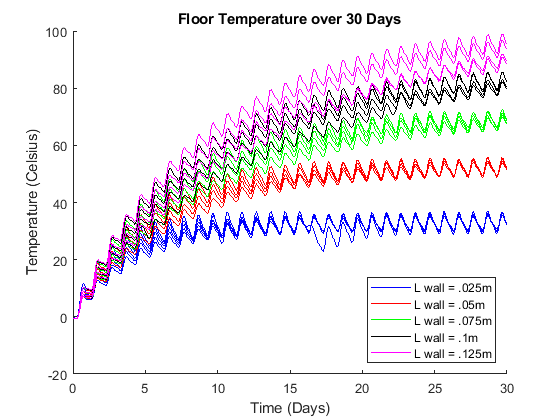

%Plotting Temperature of floor and inside air for all possible combinations
%of L_wall and L_floor

clf
hold on
figure(1)  %Plotting floor temperature values for each combination of Lwall & Lfloor
for k=1:(length(L_floor) * length(L_wall_vals))  %Looping through every combination of Lwall and Lfloor
    if k < 6
        p1 = plot(times(:, 1)./(60*60*24), Tfloor_total(:, k), 'b');  %Assigning a color for each Lwall value
    elseif k > 6 && k < 11
        p2 = plot(times(:, 2)./(60*60*24), Tfloor_total(:, k), 'r');
    elseif k > 11 && k < 16
        p3 = plot(times(:, 3)./(60*60*24), Tfloor_total(:, k), 'g');
    elseif k > 16 && k < 21
        p4 = plot(times(:, 4)./(60*60*24), Tfloor_total(:, k), 'k');
    elseif k > 21 && k < 26
        p5 = plot(times(:, 5)./(60*60*24), Tfloor_total(:, k), 'm');
    end
end
xlabel('Time (Days)')
ylabel('Temperature (Celsius)')
title('Floor Temperature over 30 Days')
legend([p1 p2 p3 p4 p5], {'L wall = .025m', 'L wall = .05m', 'L wall = .075m', 'L wall = .1m', 'L wall = .125m'}, 'Location', 'Southeast')
hold off

k=1;  %resetting k value to do another for loop instead of declaring new variable

hold on

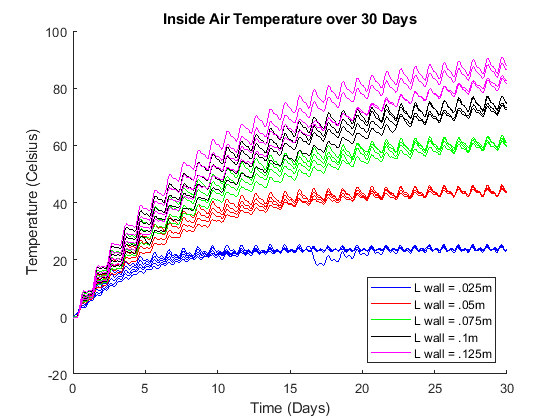

figure(2)  %Plotting inside air temperature values for each combination of Lwall & Lfloor
for k=1:(length(L_floor) * length(L_wall_vals))  %Looping through every combination of Lwall and Lfloor
    if k < 6
        p1 = plot(times(:, 1)./(60*60*24), Tair_total(:, k), 'b');  %Assigning a color for each Lwall value
    elseif k > 6 && k < 11
        p2 = plot(times(:, 2)./(60*60*24), Tair_total(:, k), 'r');
    elseif k > 11 && k < 16
        p3 = plot(times(:, 3)./(60*60*24), Tair_total(:, k), 'g');
    elseif k > 16 && k < 21
        p4 = plot(times(:, 4)./(60*60*24), Tair_total(:, k), 'k');
    elseif k > 21 && k < 26
        p5 = plot(times(:, 5)./(60*60*24), Tair_total(:, k), 'm');
    end
end
xlabel('Time (Days)')
ylabel('Temperature (Celsius)')
title('Inside Air Temperature over 30 Days')
legend([p1 p2 p3 p4 p5], {'L wall = .025m', 'L wall = .05m', 'L wall = .075m', 'L wall = .1m', 'L wall = .125m'}, 'Location', 'Southeast')
hold off

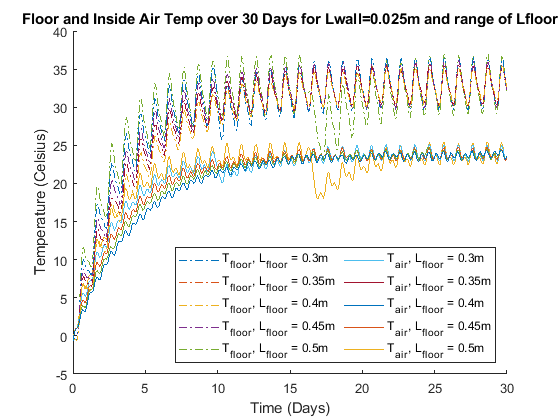

%Plotting subset of results so we can choose best combination to optimize
%our model

%Based on plots above, we should focus on L = 0.025m since that is the most
%comfortable internal air temperature
clf

k = 1;  %Resetting k so we can use again in for loop

hold on
figure(3)  %Plot possible temperatures for Lwall=0.025m (chosen from results of plots in previous section)
for k=1:(length(L_floor))
    plot(times./(60*60*24), Tfloor_total(:, k),'-.')  %Plotting floor temperature values for Lwall=0.025m and range of Lfloor values
    plot(times./(60*60*24), Tair_total(:, k))  %Plotting inside air temperature values for Lwall=0.025m and range of Lfloor values
end

xlabel('Time (Days)')
ylabel('Temperature (Celsius)')
title('Floor and Inside Air Temp over 30 Days for Lwall=0.025m and range of Lfloor')
legend({'T_f_l_o_o_r, L_f_l_o_o_r = 0.3m','T_f_l_o_o_r, L_f_l_o_o_r = 0.35m','T_f_l_o_o_r, L_f_l_o_o_r = 0.4m','T_f_l_o_o_r, L_f_l_o_o_r = 0.45m','T_f_l_o_o_r, L_f_l_o_o_r = 0.5m','T_a_i_r, L_f_l_o_o_r = 0.3m','T_a_i_r, L_f_l_o_o_r = 0.35m','T_a_i_r, L_f_l_o_o_r = 0.4m','T_a_i_r, L_f_l_o_o_r = 0.45m','T_a_i_r, L_f_l_o_o_r = 0.5m'},'Location','southeast','NumColumns',2)
hold off

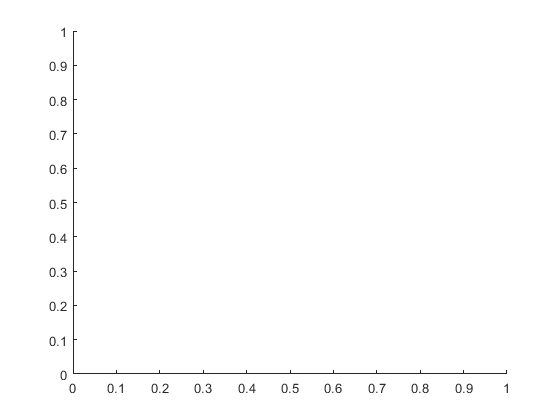

% Using Lfloor = 0.4m and Lwall = 0.025m since it results in the most comfortable and consistent internal air temperature
clf
hold on

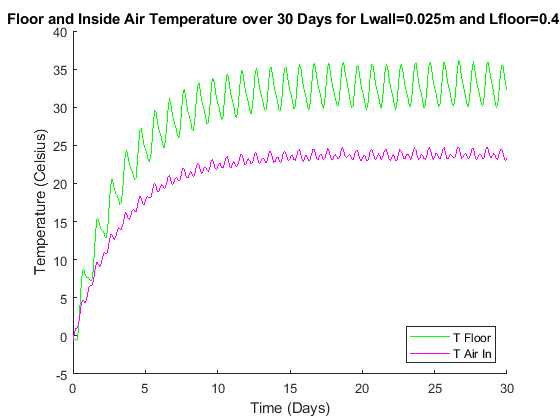

figure(4)

p1 = plot(times(:, 3)./(60*60*24), Tfloor_total(:, 3),'g');  %Plotting floor temperatures
p2 = plot(times(:, 3)./(60*60*24), Tair_total(:, 3),'m');  %Plotting inside air temperatures
xlabel('Time (Days)')
ylabel('Temperature (Celsius)')
title('Floor and Inside Air Temperature over 30 Days for Lwall=0.025m and Lfloor=0.4m')
legend('T Floor', 'T Air In', 'Location', 'southeast')
hold off